# C3 Lab report

#  Digital Modulation

Group 1 section 4

Name: 

- Ahmed Abd-Elmotagly Ahmed Metwally       1806861

- Sarah Meinsi Fahmy                                     1807558

- Yomna Hussein Mahmoud                            1804491

## Generating random bits and constellation diagram for BPSK

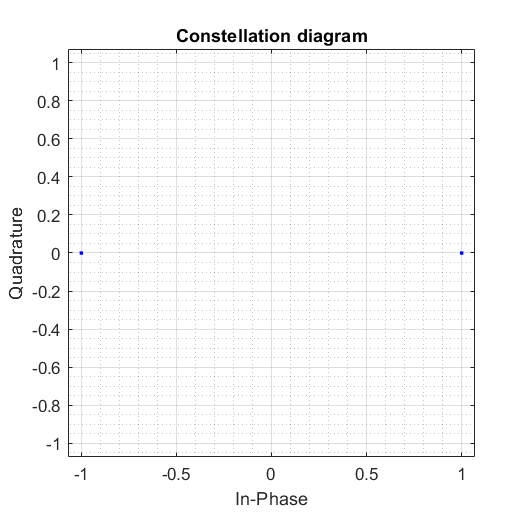

N=10000; % no. of bits
data = randi([0 1],N,1);
bpskModulator = comm.BPSKModulator;
bpskModulator.PhaseOffset =0;
modData = bpskModulator(data);
scatterplot(modData)
grid on ;
grid minor;
title('Constellation diagram');

## Up sampling

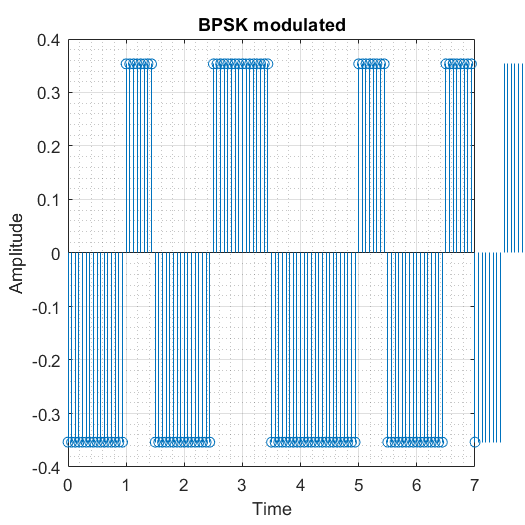

L=8;
ts= 0.5;
Up_data=upsample(modData,L);
gtx=(1/(sqrt(L)))*rectpulse(modData,L); % normalized
t = linspace(0,N*ts,length(Up_data));
stem (t,real(gtx));
xlim ([0 7]);
ylim ([-0.4 0.4]);
grid on;
grid minor;
title('BPSK modulated');
xlabel('Time');
ylabel ('Amplitude');

## Additive white gaussian noise

S=[-10 5 10]

S =    -10     5    10


values={'-10','5','10'}

values = 1×3 cell array
    {'-10'}    {'5'}    {'10'}


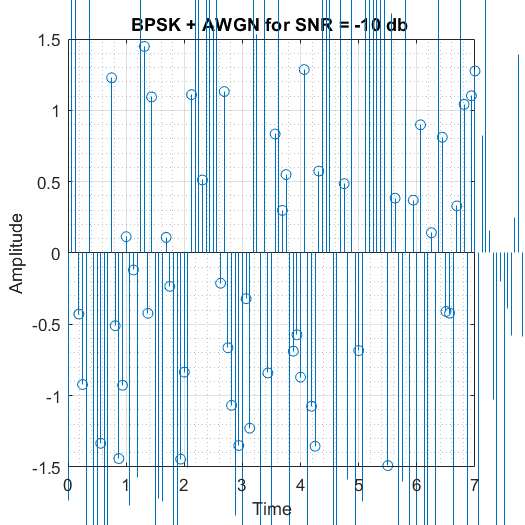

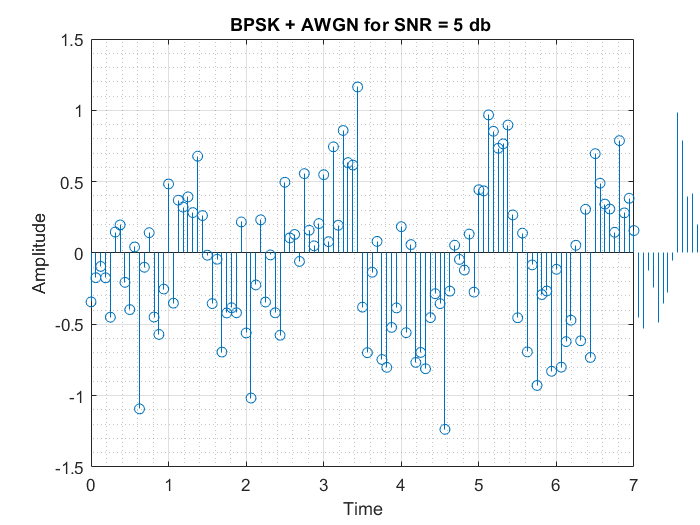

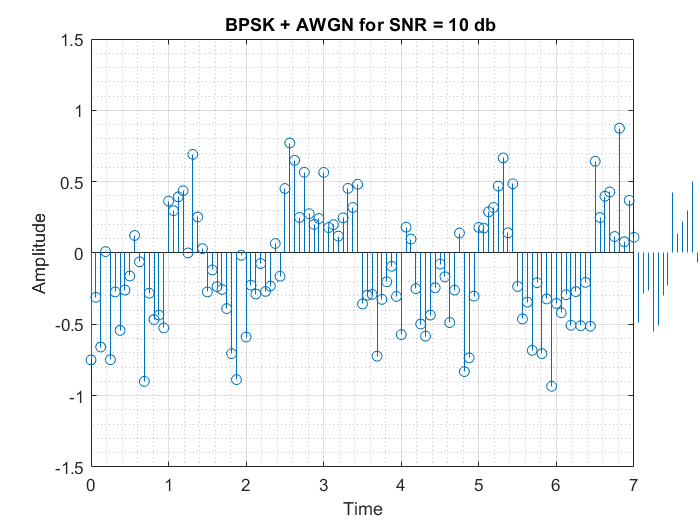

for i=1:3
grx= awgn(gtx,S(i));
t = linspace(0,N*ts,length(Up_data));
figure (i);
 stem (t,real(grx));
xlim ([0 7]);
ylim ([-1.5 1.5]);
grid on;
grid minor;
title(sprintf('BPSK + AWGN for SNR = %s db ',values{i}));

xlabel('Time');
ylabel ('Amplitude');


## Matched filter

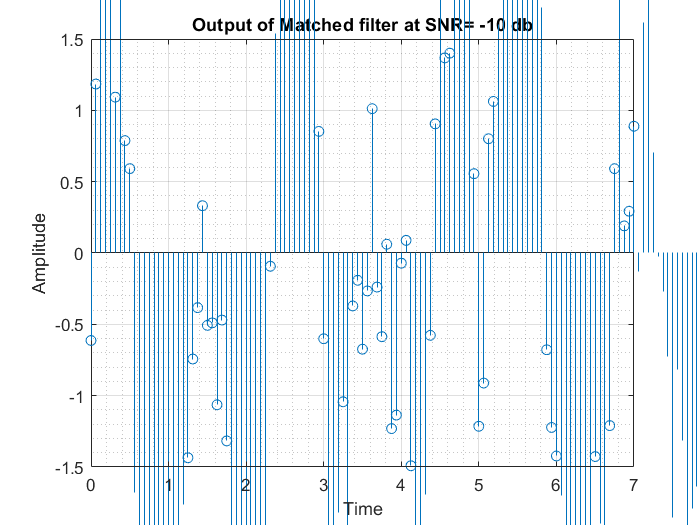

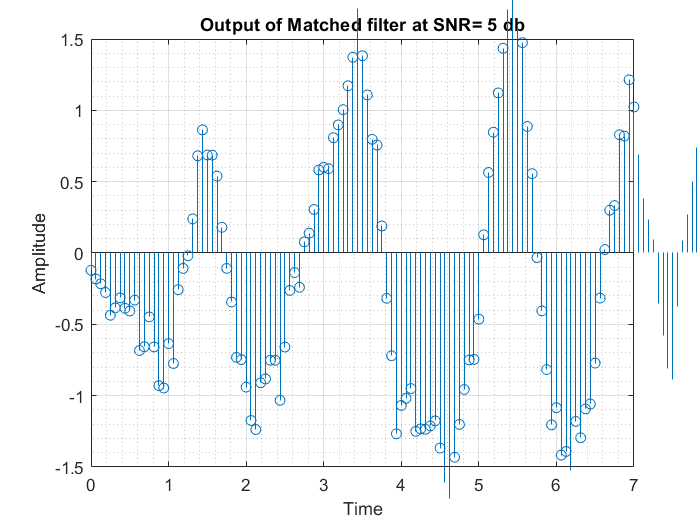

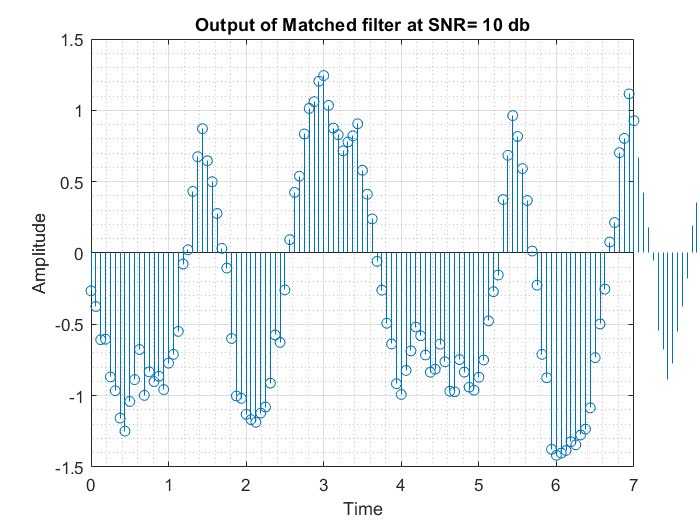

M=8;
matched = (1/sqrt(M))*ones(1,L);
filtered= conv(grx,matched);
t = linspace(0,N*ts,length(filtered));
figure
stem (t,real(filtered));
xlim ([0 7]);
ylim ([-1.5 1.5]);
grid on;
grid minor;
title(sprintf('Output of Matched filter at SNR= %s db',values{i}));
xlabel('Time');
ylabel ('Amplitude');

## Down sampling

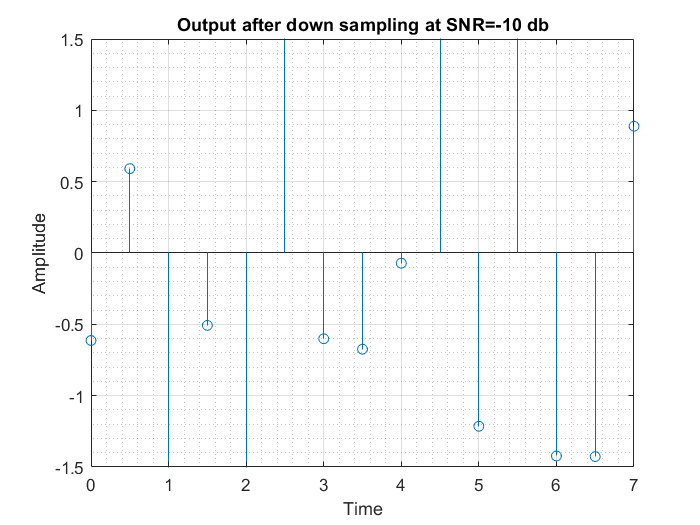

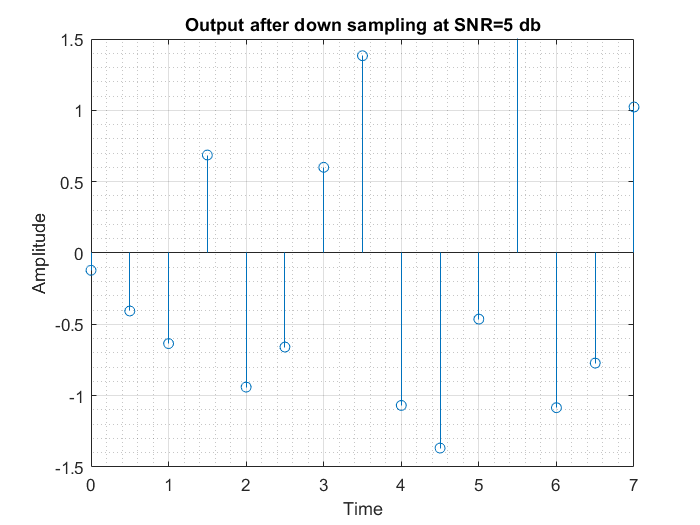

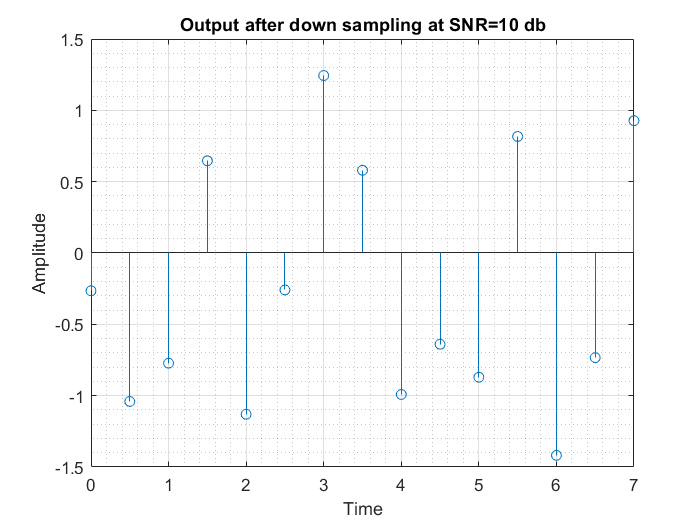

down_data=downsample (filtered,M,0);
t = linspace(0,N*ts,length(down_data));
figure
stem (t,real(down_data));
xlim ([0 7]);
ylim ([-1.5 1.5]);
grid on;
grid minor;
title(sprintf('Output after down sampling at SNR=%s db',values{i}));
xlabel('Time');
ylabel ('Amplitude');

## Constellation

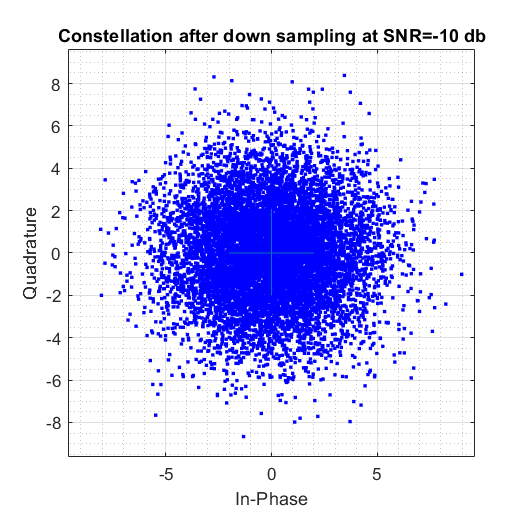

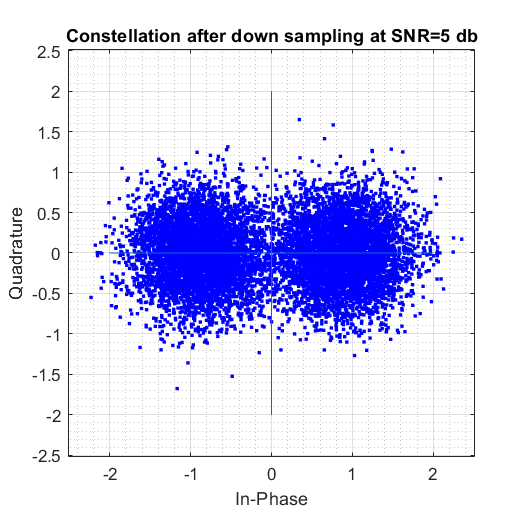

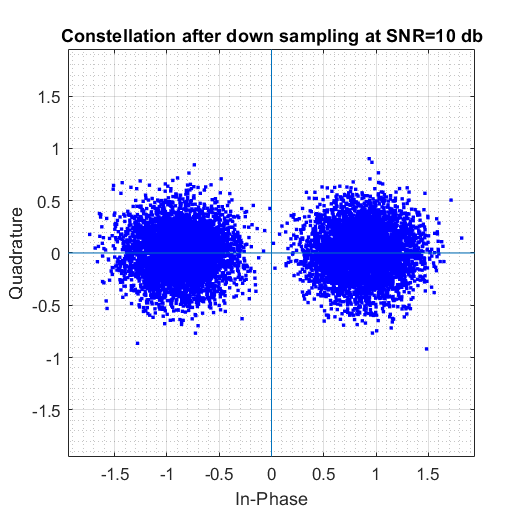

figure
scatterplot(down_data);
grid on;
grid minor;
title(sprintf('Constellation after down sampling at SNR=%s db',values{i}));
line([0 0], [-2 2]);
line([-2 2], [0 0]);

end

## BER VS SNR

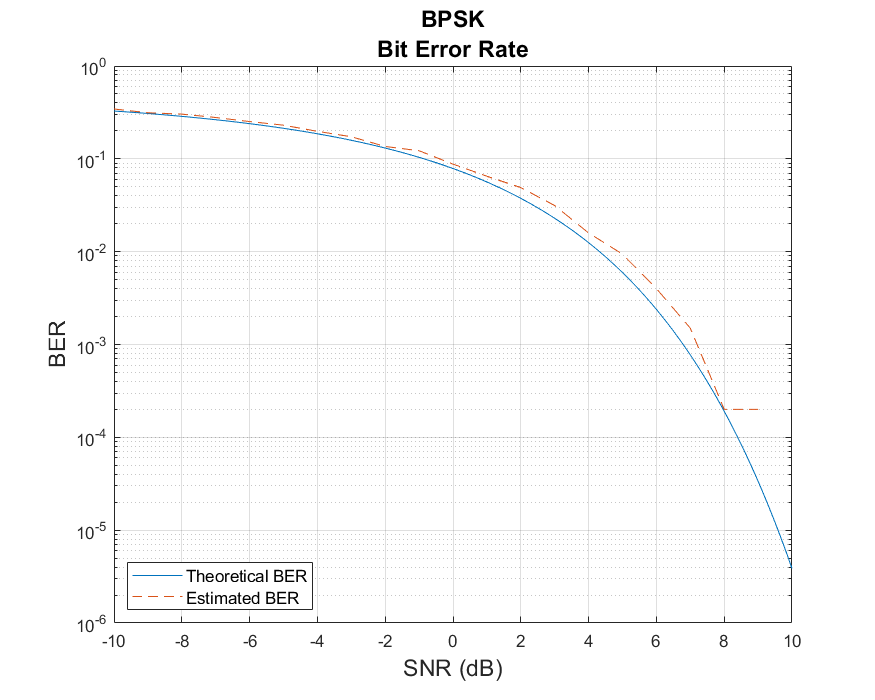

SNR_db = -10:10;
Ps = bandpower (data);
Err = SNR_db;
for i = 1:length(SNR_db)
new = awgn(gtx,SNR_db(i),Ps); 
y1 = conv(new,matched); 
y1 = y1(M:end); 
demodData = downsample(y1,M); 
rxData = demodData;
index1 = find(real(demodData)<0);
index0 = find(real(demodData)>0);
rxData(index1) = 1;
rxData(index0) = 0;
Err(i) = biterr(data,rxData); 
end
BER= Err/N;
SNR_db_th = -10:0.1:10;
SNR = 10.^(SNR_db_th/10);
Eb_No = SNR;
BER_th = (1/2)*erfc(sqrt(Eb_No));
figure('position',[680 420 700 560]);
semilogy(SNR_db_th,BER_th);
hold on
semilogy(SNR_db,BER,'--');
hold off;
grid on;
xlabel('SNR (dB)','FontSize',14);
ylabel('BER','FontSize',14);
title({'BPSK','Bit Error Rate'},'FontSize',14);
legend({'Theoretical BER','Estimated BER'},'FontSize',10);
legend('Location','southwest');